A = [1,2,3,4];
[c,t] = getData("Bangladesh")

c =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     3     3     3     3     3     5     5     8    10    14    18    20    24    27    33    39    39    44    48    48    48    49    51    54    56    61    70


t = 737836

datn = t:t+length(c)-2

datn =       737836      737837      737838      737839      737840      737841      737842      737843      737844      737845      737846      737847      737848      737849      737850      737851      737852      737853      737854      737855      737856      737857      737858      737859      737860      737861      737862      737863      737864      737865      737866      737867      737868      737869      737870      737871      737872      737873      737874      737875      737876      737877      737878      737879      737880      737881      737882      737883      737884      737885


TimeDT = datetime(datn, 'ConvertFrom', 'juliandate', 'Format', 'yyyy-MM-dd');   %or as appropriate for format you want displayed
% plot(TimeDT, Displacement)

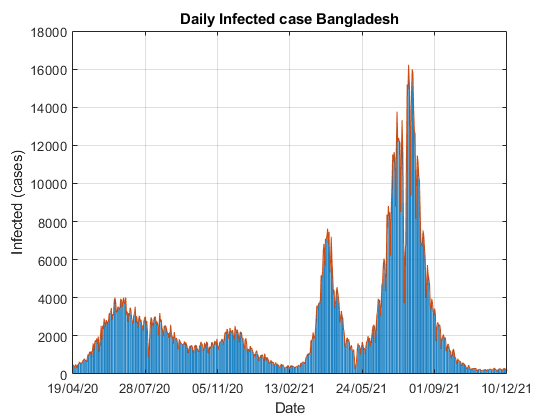

str = '#cc4d13';
color = sscanf(str(2:end),'%2x%2x%2x',[1 3])/255;
figure
% plot(x, y, )

bar(datn,diff(c));
hold on;
plot(datn,diff(c),'Color',color)
% bar(TimeDT,diff(c));
% xlim([datn(1),datn(end)]);
% datetick('x','keepticks','keeplimits')
xlabel('Date')
ylabel('Infected (cases)')
% datetick('x',10,'keeplimits')
title("Daily Infected case Bangladesh")
datetick('x',20,'keepticks')
grid on;
print(gcf,'12.png','-dpng','-r600')

function [C,T] = getData(country)
%Read covid-19 data from www.worldometers.info/coronavirus
    if strcmpi(country,'world')
        url = 'https://www.worldometers.info/coronavirus/';
    else
        if ~contains(country,'/')
            url = 'https://www.worldometers.info/coronavirus/country/';
            url = strcat(url,lower(country));
        else
            url = 'https://www.worldometers.info/coronavirus/';
            url = strcat(url,lower(country));
        end
    end
    try
        html = webread(url);
    catch
        fprintf('No information for %s found.\n',country);
        C = [];
        T = [];
        return
    end
    pattern1 = 'Total Cases';% start of list
    pattern2 = 'responsive';     % end of list
    list = extractBetween(html, pattern1, pattern2);
    list1 = extractBetween(list{1}, 'categories: ', '}');
    list2 = extractBetween(list{1}, 'data: ', '}');
    C = str2num(cell2mat(list2));
    D = list1';
    D = extractBetween(D, '"', '"');
    T = datenum(strcat('2020.',strrep(D{1},' ','.')),'yyyy.mm.dd');
end


